## 一个切片上一个齿时变啮合刚度

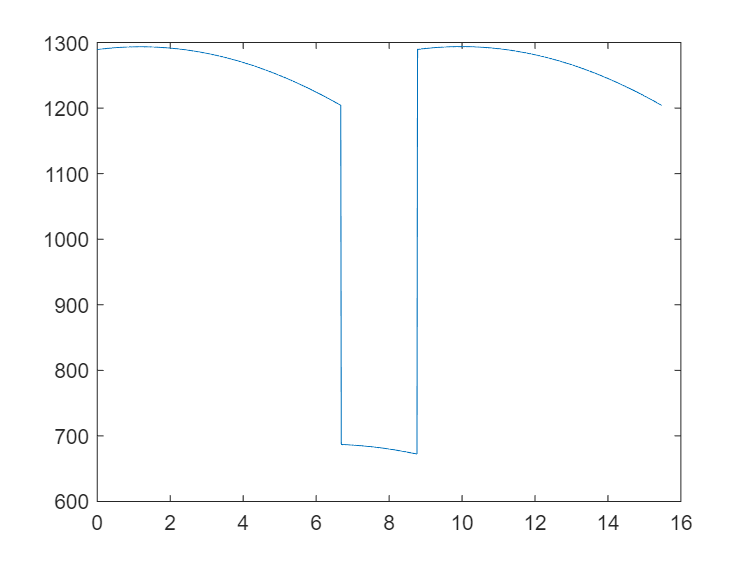

clc
clear
close all

P1_Gear_Parameters
P2_Sun_Star_new

figure(1)
% plot(w12*180/pi,k12)
% hold on

[w,k]=Peorid_tooth(w12,k12,z1);
plot(w,k)

## 一个切片上一个齿扩展到多个齿

close all

[w ,k]=Peorid_tooth(w12,k12,z1);


w1 = w*pi/180;
k1 = k;

w_max = w1(end);

w2 = w1+w_max;
w3 = w2+w_max;

ww = [w1(1,1:end-1) w2(1,1:end-1) w3];
kk = [k1(1,1:end-1),k1(1,1:end-1),k1];

figure(2)
plot(ww,kk)

## 各切片叠加求和→综合时变啮合刚度

% 计算太阳轮上的啮合刚度
N       =  min(b1,b2)/bN;               % 切片数量
Theta_L =  min(b1,b2)*tan(Bb1)/rb1;     % 最大滚动角
delta   =  Theta_L/N;                   % 相邻切片的转角差（弧度制）

% 插值
w1 = w12(1):delta:w12(end);
k1 = spline(w12,k12,w1);
k_all = k1;

for k = 1:N-1
    
    
end